load("\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_09_28_realisticScatter_variousIMCL\statistics.mat")

## IMCLが平均音速値に与える影響とEMCLが平均音速値に与える影響が独立しているかどうかを視覚的に確認する．

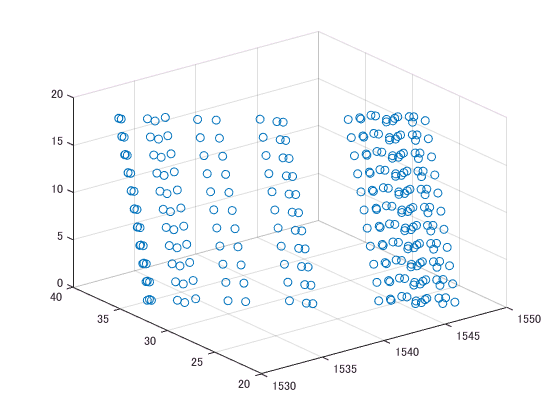

figure;
[a,b] = size(aveSOS2);
scatter3(reshape(aveSOS2,a*b,1),reshape(rate_EMCLs,a*b,1),reshape(rate_IMCLs,a*b,1));

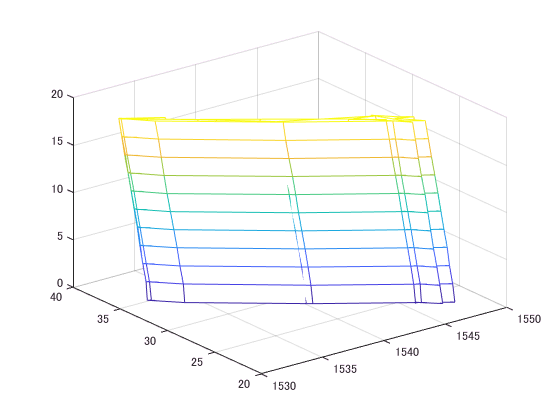

mesh(aveSOS2,rate_EMCLs,rate_IMCLs);

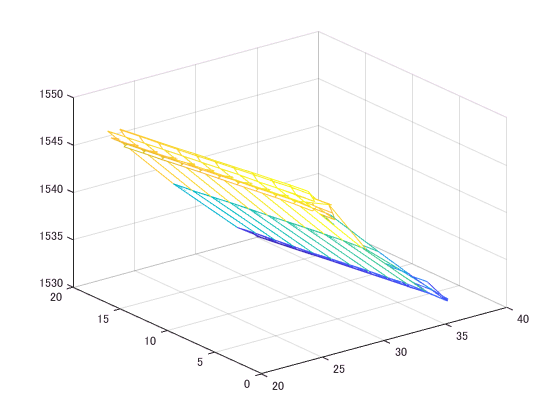

mesh(rate_EMCLs,rate_IMCLs,aveSOS2);

3次元プロットしてもなんの意味もない．

## 平均音速値のEMCL率に関する変化率と平均音速値のIMCL率に関する変化率が等しいかどうか検証する．

aveSOSのdim={IMCL，EMCL}

## 手法１：レンジに注目した手法

■平均音速値のIMCL率に関する変化率

サンプル数をEMCL構造の種類数におく．IMCL0%と2%の値から平均音速値の変化率を算出する．これらをヒストグラムプロットする．平均値を求める．

■平均音速値のEMCL率に関する変化率

サンプル数をIMCLの種類数におく．EMCL%の最大値とEMCL%の最小値から平均音速値の変化率を算出する．これらをヒストグラムプロットする．平均値を求める．

## 手法２：単回帰による手法

■平均音速値のIMCL率に関する変化率

横軸にIMCL率，縦軸に平均音速値をとり，全サンプル分プロットする．

これらプロットデータに対して回帰直線を求めて回帰係数を求める．

■平均音速値のEMCL率に関する変化率

横軸にIMCL率，縦軸に平均音速値をとり，全サンプル分プロットする．

これらプロットデータに対して回帰直線を求めて回帰係数を求める．

手法１

delta_SOS_by_IMCL1 = zeros(1,25);
delta_SOS_by_EMCL1 = zeros(1,11);
for ii = 1:25
    delta_SOS_by_IMCL1(1,ii) = -(aveSOS2(1,ii)-aveSOS2(end,ii))/2;
end
[max_EMCL,ind_max_EMCL] = max(max(rate_EMCLs));
[min_EMCL,ind_min_EMCL] = min(min(rate_EMCLs));
for ii = 1:11
    delta_SOS_by_EMCL1(1,ii) = (aveSOS2(ii,ind_max_EMCL)-aveSOS2(ii,ind_min_EMCL))/(max_EMCL-min_EMCL);
end
ave_delta_SOS_by_IMCL1 = mean(delta_SOS_by_IMCL1)

ave_delta_SOS_by_IMCL1 = -1.2205

ave_delta_SOS_by_EMCL1 = mean(delta_SOS_by_EMCL1)

ave_delta_SOS_by_EMCL1 = -1.2434

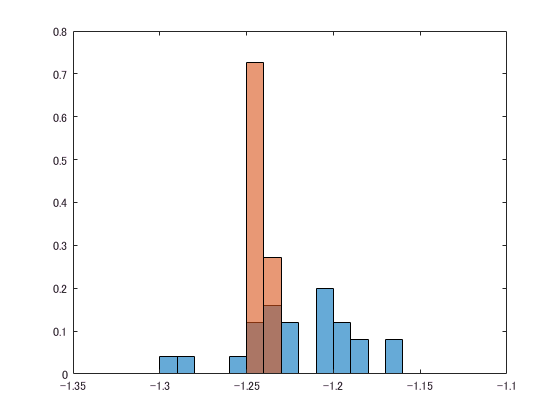

figure;
h1 = histogram(delta_SOS_by_IMCL1,'Normalization','probability');
hold on
h2 = histogram(delta_SOS_by_EMCL1,'Normalization','probability');
xlim([-1.35 -1.1])
h1.Normalization = 'probability';
h1.BinWidth = 0.01;
h2.Normalization = 'probability';
h2.BinWidth = 0.01;
hold off

手法２

Rで行う．